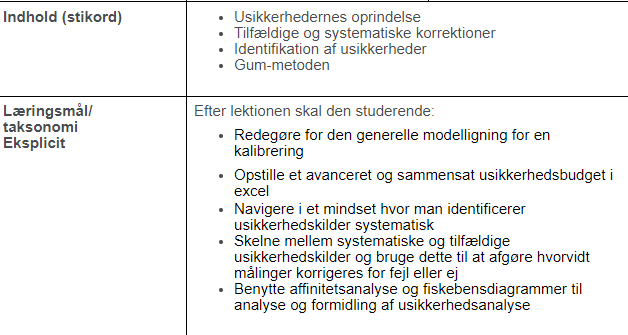

clc; clear all;
u = symunit;

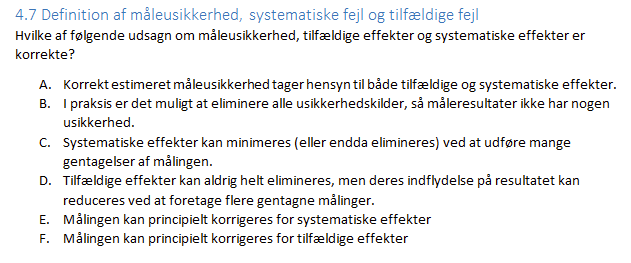

A. Ja, der skal tages højde for begge

B. Nej, man kan tage højde for så mange relevante usikkerheder som muligt. Målingen kan være mere og mere præcis, usikkerheden vil propagere mod 0, men aldrig blive 0

C. Ja, systematiske kan minimeres i praksis, og elimineres teoretisk

D. Ja, ved flere målinger vil sandsynligheden for tilfældige effekter formindskes, det er så bare svært at sige hvad den tilfældige effekt er

E. Ja da

F. Ikke med det samme, der skal foretages mange målinger, for at spore sig ind på hvad den tilfældige effekt kan være. Så over tid ja, men ikke ved opstart

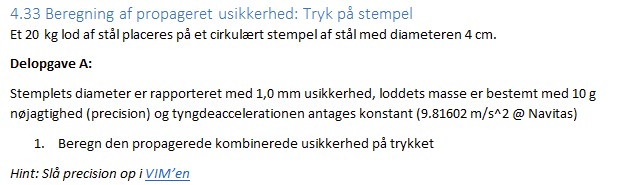

% Værdier
m_v = 20*u.kg;
D_v = unitConvert(4*u.cm,"SI");


g = 9.81602 * u.m/u.s^2;


% Fejl
fejl_m = unitConvert(10*u.g,"SI");
fejl_D = unitConvert(1*u.mm,"SI");

% Tryk
syms m D
A = pi*(D/2)^2;
F = m*g;

P = F/A;

Pnom = m_v*g/(pi*(D_v/2)^2);
Pnom = vpa(unitConvert(Pnom, u.kPa), 5)

$$Pnom = 156.23\,\mathrm{kPa}$$


U = Opbhobningsloven(P, [m D], [m_v D_v], [fejl_m fejl_D])

$$U = \frac{\sqrt{190868336680711672256426341394076805625}}{562949953421312\,\pi }\,\frac{\mathrm{kg}}{m\,s^{2}}$$

U = vpa(unitConvert(U, u.kPa), 3)

$$U = 7.81\,\mathrm{kPa}$$

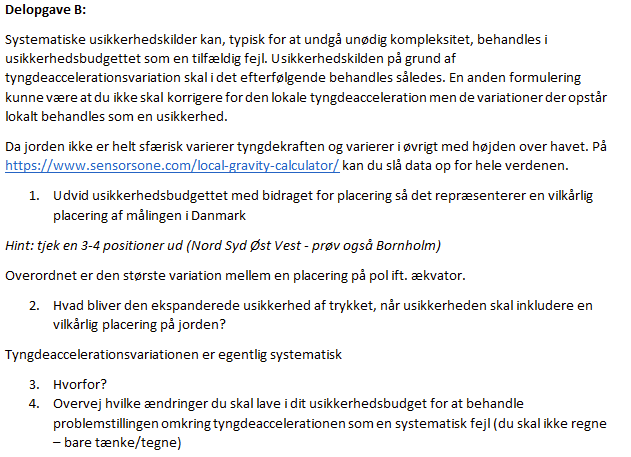

% Værdier
m_v = 20*u.kg;
D_v = unitConvert(4*u.cm,"SI");


g1 = 9.817 * u.m/u.s^2; % Vendsyssel
g2 = 9.81544 * u.m/u.s^2; % Esbjerg
g3 = 9.81559 * u.m/u.s^2; % København
g4 = 9.78021 * u.m/u.s^2; % Kenya

gs = [g1, g2, g3, g4];


% Fejl
fejl_m = unitConvert(10*u.g,"SI");
fejl_D = unitConvert(1*u.mm,"SI");

% Tryk
syms m D
A = pi*(D/2)^2;
F = m*gs;

P = F/A;

for i = 1:length(gs)
    U = Opbhobningsloven(P(i), [m D], [m_v D_v], [fejl_m fejl_D]);
    Us(i) = vpa(unitConvert(U, u.Pa), 6);
end


Us = vpa(Us, 6)

$$Us = \left(\begin{array}{cccc} 7812.51\,\mathrm{Pa} & 7811.27\,\mathrm{Pa} & 7811.39\,\mathrm{Pa} & 7783.23\,\mathrm{Pa} \end{array}\right)$$